clear

addpath('matlab_functions\')

#### Compute Sensitivity

Model = myModel;
freqs = [3600]; % (Hz)

for freq = freqs
    tic
    [S_sigma, S_mu] = Model.Sensitivity(freq);
    fprintf('Compute %g Hz sensitivity took %.2f seconds\n', freq, toc)
    
    voxels_center = Model.voxels.center;
    sigma = Model.voxels.sigma;
    mur   = Model.voxels.mur;
    
    fname = sprintf('data/Sensitivity_%dHz_%s.mat', freq, datetime('now','Format','MMdd-HHmm'));
    save(fname, 'S_sigma','S_mu','voxels_center','sigma','mur','freq')
end

Compute 3600 Hz sensitivity took 37.97 seconds


#### Visualize Sensitivity

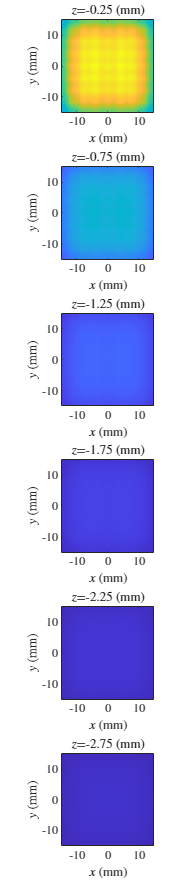

load('data\Sensitivity_3600Hz.mat')
VisualizeSensitivity(S_sigma, voxels_center, 'all')

function VisualizeSensitivity(S, element_centers, varargin)

z = unique(element_centers(3,:));
z = sort(z, 'descend');

if isempty(varargin) || strcmpi(varargin{1}, 'all')
    S_norm = vecnorm(S);
else
    S_norm = abs(S(varargin{1},:));
end

figure
tl = tiledlayout(length(z),1, 'TileSpacing','tight', 'Padding','none');
set(gcf, 'Position',[10 10 flip(tl.GridSize) .* [300 250]])
for k = 1:length(z)
    mask = element_centers(3,:) == z(k);
    c = reshape(S_norm(mask), sqrt(sum(mask)),[]);

    x = [min(element_centers(1,mask)) max(element_centers(1,mask))] * 1e3;
    y = [min(element_centers(2,mask)) max(element_centers(2,mask))] * 1e3;

    nexttile
    imagesc(x, y, c.', [0 max(S_norm)])
    axis square xy
    title(sprintf('$z$=%g (mm)',z(k)*1e3), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')
end

end